# Panda Map Column

## Grid

grid = OctoGrid(2,2,2,10);

% add column
grid.addBox(1.25,0.9,0,0.2,0.2,1.5)

## Robot

% robot base transformation (move to x - 1m, y - 1m)
Tbase = eye(4);
Tbase(1:2,4) = [1 1]';


% set joints positions
joints = [0 0 0 0 0 0 0];

[robot_transforms] = GeometricPandaMATLAB(joints, Tbase);

## Show grid

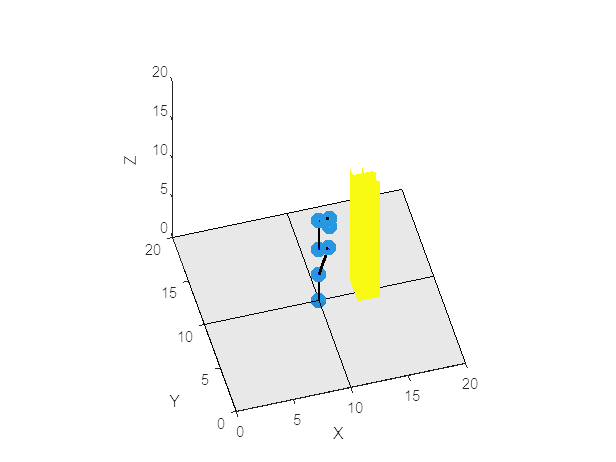

% display
grid.showGridVol3D(grid.grid,'floor',true,'height',false)
hold on
axis equal
showPanda(robot_transforms,10)
hold off

## Generate goal points

% trajectory generation points (xyz position, xyz angles)
control_points = [1.088 1 0.926 0 0 0;
                  1.4 1.2 0.5 0 0 0]; 


## Calculate motion plan using kinematics, ignoring obstacles

% calculate list of joints positions using kinematics
[joints_positions_no_obstacles, EE_positions_no_obstacles, EE_distances, q_velocities] = kinematics_trajectory(control_points(2,:), Tbase, zeros(7,1));

## Display goal points

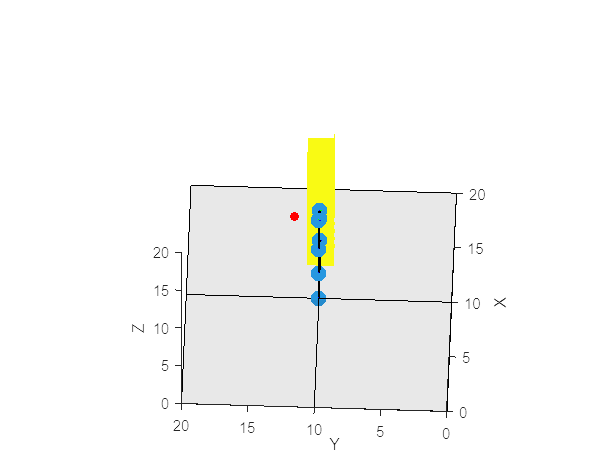

% Multiply the coordinates by 10 to scale the points
x = control_points(:, 1) * 10;
y = control_points(:, 2) * 10;
z = control_points(:, 3) * 10;

% display points
hold on

% Create a scatter plot with solid red points
scatter3(x, y, z, 'filled', 'MarkerFaceColor', 'red');

## Draw Calculated Poses

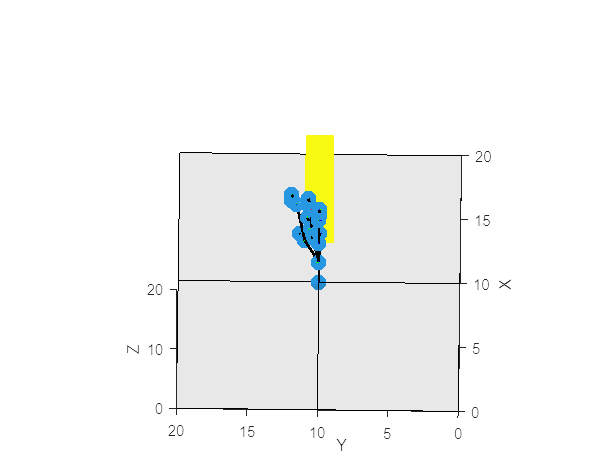

% draw calculated EE trajectory
% hold on
plot3(EE_positions_no_obstacles(1,:)*10,EE_positions_no_obstacles(2,:)*10,EE_positions_no_obstacles(3,:)*10)

% draw initial pose
[robot_transforms] = GeometricPandaMATLAB(joints_positions_no_obstacles(:,1), Tbase);
showPanda(robot_transforms,10)

% draw finish pose
[robot_transforms] = GeometricPandaMATLAB(joints_positions_no_obstacles(:,end), Tbase);
showPanda(robot_transforms,10)

% draw mid pose
[robot_transforms] = GeometricPandaMATLAB(joints_positions_no_obstacles(:,ceil(length(joints_positions_no_obstacles)/6)), Tbase); % take pose after 1/6 steps ( poses get denser towards goal)
showPanda(robot_transforms,10)

## Calculate obstacles repulsive field

## Calculate motion plan using kinematics, avoiding obstacles